clear; clc; close all;

## 雷达相关参数设定

c = 3e8;%光速
fc = 77e9;%起始频率
B = 300e6;%带宽
Tc = 40e-6;%调频脉冲时间
Num_chirps = 256;%单帧包含的脉冲
Num_ADC = 512;%单脉冲ADC采样点
Num_frames = 50;%帧数
Num_tx = 1;
Num_rx = 8;

Tf = Tc*Num_chirps;%单帧时间
Fs = Num_ADC/Tc;%采样频率
S = B/Tc;%调频斜率
lambda = c/fc;%波长
Rmax = Fs*c/(2*S);%最大不模糊距离
Rres = c/2/B;%距离分辨率
Vmax = lambda/4/Tc;%最大不模糊速度
Vres = lambda/2/Tf;%速度分辨率
d_rx = lambda/2;
d_tx = 4*d_rx;

## 仿真参数

N = Num_ADC*Num_chirps*Num_frames;%总采样点
t = linspace(0,Tc*Num_chirps*Num_frames,N);%仿真时间轴
t_chirp = linspace(0,Tc,Num_ADC);%单脉冲时间轴
R = linspace(0,Rmax,Num_ADC); %距离轴
V = linspace(-Vmax, Vmax, Num_chirps); %速度轴
Ang_ax = -90:90; %角度轴

## 天线位置

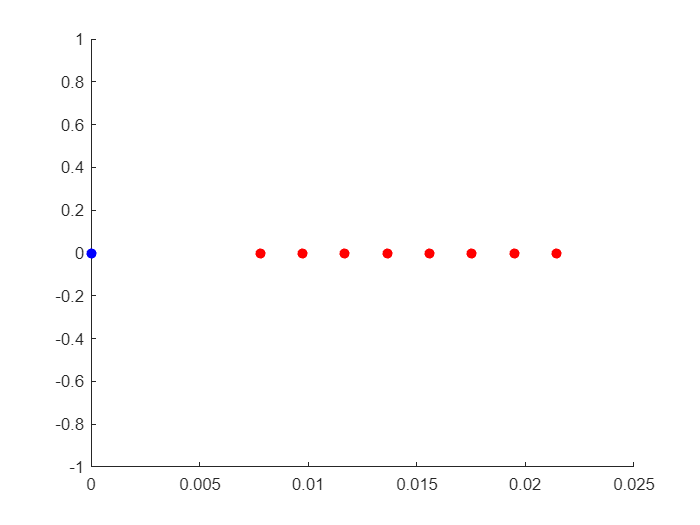

tx_loc = cell(1,Num_tx);
for i = 1:Num_tx
   tx_loc{i} = [(i-1)*d_tx 0];
   scatter(tx_loc{i}(1),tx_loc{i}(2),'b','filled')
   hold on
end

rx_loc = cell(1,Num_rx);
for i = 1:Num_rx
   rx_loc{i} = [tx_loc{Num_tx}(1)+d_tx+(i-1)*d_rx 0];
   scatter(rx_loc{i}(1),rx_loc{i}(2),'r','filled')
end

## 运动目标参数

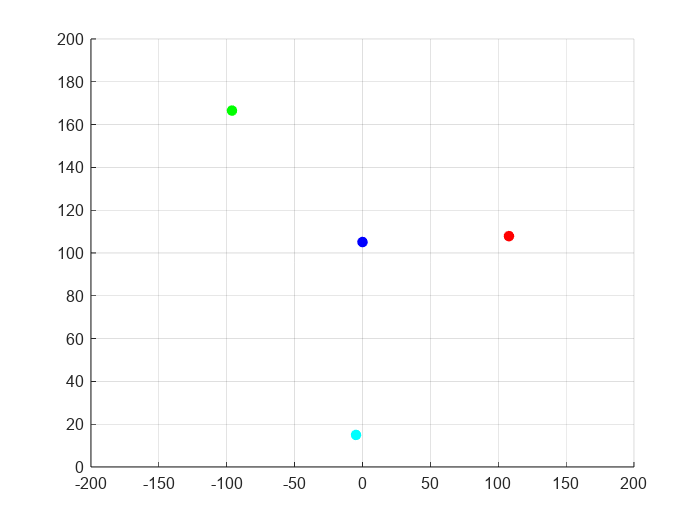

%目标
tar1_radial = 100;
tar1_angle = 0;
tar1_v = 10;
tar1_location = get_target_location(tar1_radial,tar1_angle,tar1_v,N,t);
tar2_radial = 150;
tar2_angle = 45;
tar2_v = 5;
tar2_location = get_target_location(tar2_radial,tar2_angle,tar2_v,N,t);
tar3_radial = 200;
tar3_angle = -30;
tar3_v = -15;
tar3_location = get_target_location(tar3_radial,tar3_angle,tar3_v,N,t);
%目标
% tar4_radial = 8;
% tar4_angle = -30;
% tar4_v = 0.2;
% tar4_location = get_target_location(tar4_radial,tar4_angle,tar4_v,N,t);
tar4_location = get_target_location_xy(-15,15,20,0,N,t);
figure
for i=1:Num_frames
    n = Num_ADC*Num_chirps*i;
    scatter(tar1_location(n,1),tar1_location(n,2),40,'b','filled');
    hold on
    scatter(tar2_location(n,1),tar2_location(n,2),40,'r','filled');
    hold on
    scatter(tar3_location(n,1),tar3_location(n,2),40,'g','filled');
    hold on
    scatter(tar4_location(n,1),tar4_location(n,2),40,'cyan','filled');
    xlim([-200,200]);
    ylim([0,200]);
    hold off
    grid on
    pause(0.1);
%     if mod(i,20) == 0
%         saveas(gcf, ['png/target_real_loaction_' num2str(round(i*Tf,1)) 's.png'])
%     end
end

## 回波时延计算

delays_tar1 = cell(1,Num_rx);
delays_tar2 = cell(1,Num_rx);
delays_tar3 = cell(1,Num_rx);
delays_tar4 = cell(1,Num_rx);
for i = 1:Num_rx
    % 计算每个采样点时，信号经过的时延 
    delays_tar1{1,i} = (vecnorm(tar1_location-repmat(rx_loc{i},N,1),2,2)+vecnorm(tar1_location-repmat(tx_loc{1},N,1),2,2))/c; 
    delays_tar2{1,i} = (vecnorm(tar2_location-repmat(rx_loc{i},N,1),2,2)+vecnorm(tar2_location-repmat(tx_loc{1},N,1),2,2))/c; 
    delays_tar3{1,i} = (vecnorm(tar3_location-repmat(rx_loc{i},N,1),2,2)+vecnorm(tar3_location-repmat(tx_loc{1},N,1),2,2))/c; 
    delays_tar4{1,i} = (vecnorm(tar4_location-repmat(rx_loc{i},N,1),2,2)+vecnorm(tar4_location-repmat(tx_loc{1},N,1),2,2))/c; 
end

## 回波信号计算

phase = @(t,fc) 2*pi*(fc.*t+S/2*t.^2); % 发射信号相位构建匿名函数
mixed = cell(Num_tx,Num_rx);
for i = 1:Num_tx
    for j = 1:Num_rx
        disp(['Processing Channel: ' num2str(j) '/' num2str(Num_rx)]);
        for k = 1:Num_chirps*Num_frames
            % 处理单个脉冲信号
            phase_t = phase(t_chirp,fc);%发射信号相位
            phase_1 = phase(t_chirp-delays_tar1{i,j}(k*Num_ADC),fc); %接收信号的相位(假设快时间下目标位置不变)
            phase_2 = phase(t_chirp-delays_tar2{i,j}(k*Num_ADC),fc);
            phase_3 = phase(t_chirp-delays_tar3{i,j}(k*Num_ADC),fc);
            phase_4 = phase(t_chirp-delays_tar4{i,j}(k*Num_ADC),fc);
            
            signal_t((k-1)*Num_ADC+1:k*Num_ADC) = exp(1j*phase_t);%发射信号
            signal_1((k-1)*Num_ADC+1:k*Num_ADC) = exp(1j*(phase_t - phase_1));%目标回波信号
            signal_2((k-1)*Num_ADC+1:k*Num_ADC) = exp(1j*(phase_t - phase_2));
            signal_3((k-1)*Num_ADC+1:k*Num_ADC) = exp(1j*(phase_t - phase_3));%目标回波信号
            signal_4((k-1)*Num_ADC+1:k*Num_ADC) = exp(1j*(phase_t - phase_4));%目标回波信号
        end
        mixed{i,j} = signal_1+signal_2+signal_3+signal_4;% 中频信号
    end
end

Processing Channel: 1/8
Processing Channel: 2/8
Processing Channel: 3/8
Processing Channel: 4/8
Processing Channel: 5/8
Processing Channel: 6/8
Processing Channel: 7/8
Processing Channel: 8/8


% for i=1:Num_rx
%     mixed{1,i} = awgn(mixed{1,i},10);
% end

## 距离速度谱

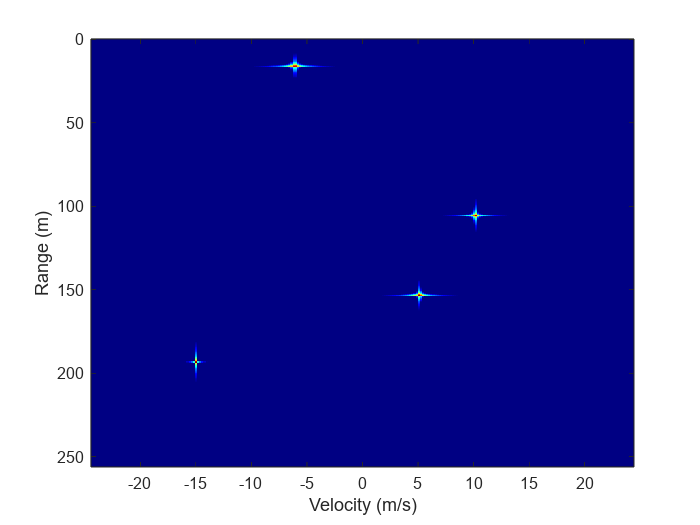

RDC = reshape(cat(3,mixed{:}),Num_ADC,Num_chirps*Num_frames,Num_rx*Num_tx); %雷达数据立方体[采样点,总脉冲数,通道数]
RDMs = zeros(Num_ADC,Num_chirps,Num_tx*Num_rx,Num_frames);% 距离-速度谱
for i = 1:Num_frames
    RD_frame = RDC(:,(i-1)*Num_chirps+1:i*Num_chirps,:);
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,Num_ADC,Num_chirps),2);%2DFFT并沿速度轴对称
end

figure
for i = 1:Num_frames

    [X,Y] = meshgrid(V,R);
    surf(X,Y,20*log10(abs(RDMs(:,:,1,i))/max(max(abs(RDMs(:,:,1,i))))));
    imagesc(V,R,20*log10(abs(RDMs(:,:,1,i))/max(max(abs(RDMs(:,:,1,i))))));
    colormap(jet);
    shading interp;
    set(gca,'clim', [-35, 0]);
    xlabel('Velocity (m/s)');
    ylabel('Range (m)');
%     xlim([-5,5]);
%     ylim([0,10]);

    pause(0.1)
%     if mod(i,20) == 0
%         saveas(gcf, ['png/RDM_' num2str(round(i*Tf,1)) 's.png'])
%     end
end

## 距离角度谱

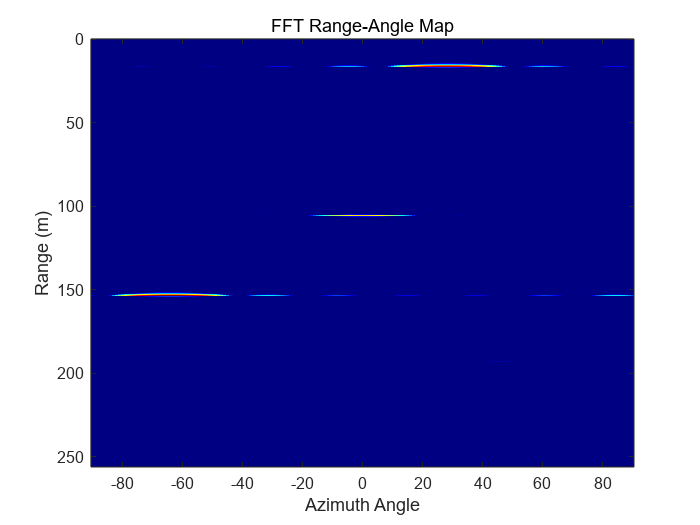

RAMs = zeros(Num_ADC,length(Ang_ax),Num_frames);
for i = 1:Num_frames
    rangeFFT = fft(RDC(:,(i-1)*Num_chirps+1:i*Num_chirps,:),Num_ADC);% 第i帧数据的距离FFT
    angleFFT = fftshift(fft(rangeFFT,length(Ang_ax),3),3);% 沿通道维的角度FFT
    range_az = squeeze(sum(angleFFT,2)); % range-azimuth map
%     range_az = angleFFT(:,1,:);
    RAMs(:,:,i) = range_az;
end

figure
for i = 1:Num_frames
    colormap(jet)
    imagesc(Ang_ax,R,20*log10(abs(RAMs(:,:,i))/max(max(abs(RAMs(:,:,i)))))); 
    xlabel('Azimuth Angle')
    ylabel('Range (m)')
    title('FFT Range-Angle Map')
    set(gca,'clim', [-20, 0]);
    pause(0.1);
%     if mod(i,20) == 0
%         saveas(gcf, ['png/RAM_' num2str(round(i*Tf,1)) 's.png'])
%     end
end

## MUSIC角度估计

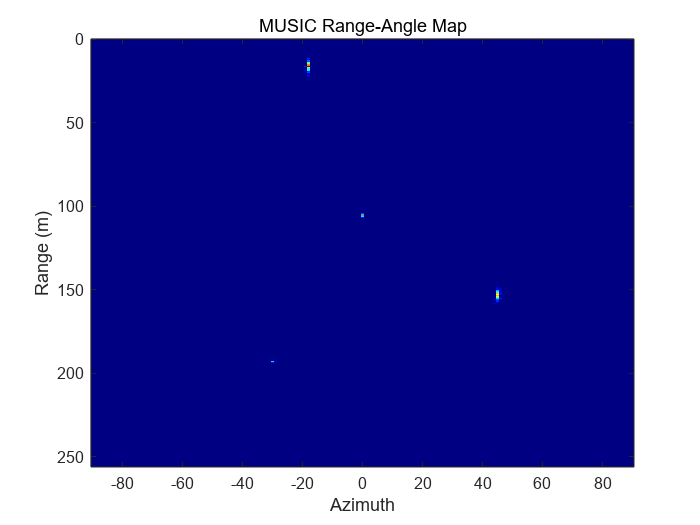

K = 4;%目标个数
rangeFFT = fft(RDC,Num_ADC,1);%先作距离维FFT
a1 = zeros(Num_tx*Num_rx,length(Ang_ax));%方向导向矢量
for k=1:length(Ang_ax)
        a1(:,k)=exp(-1i*pi*(0:Num_tx*Num_rx-1)'*sind(Ang_ax(k)));
end

range_az_music = zeros(Num_ADC,length(Ang_ax),Num_frames);%距离MUSIC角度谱
for f = 1:Num_frames
    for i = 1:Num_ADC
        A = squeeze(sum(rangeFFT(i,(f-1)*Num_chirps+1:f*Num_chirps,:),2));%第i距离单元，累计单帧下不同脉冲的通道结果[1,Num_chirps,Num_rx]->[Num_rx]
        Rxx = 1/Num_rx * (A*A');
        [Q,D] = eig(Rxx); % 分解特征向量与特征值
        [D, I] = sort(diag(D),'descend');
        Q = Q(:,I); % 排序
        Qs = Q(:,1:K); %信号分量
        Qn = Q(:,K+1:end); %噪声分量
        music_spectrum2 = zeros(1,length(Ang_ax));%角度搜索
        for k=1:length(Ang_ax)
            music_spectrum2(k)=1/(a1(:,k)'*(Qn*Qn')*a1(:,k));
        end
        range_az_music(i,:,f) = music_spectrum2;
    end
end

figure
for i=1:Num_frames
    colormap(jet)
    imagesc(Ang_ax,R,10*log10(abs(range_az_music(:,:,i))/max(max(abs(range_az_music(:,:,i)))))); 
    xlabel('Azimuth')
    ylabel('Range (m)')
    title('MUSIC Range-Angle Map')
    set(gca,'clim', [-25, 0]);
    pause(0.1)
%     if mod(i,20) == 0
%          saveas(gcf, ['png/music_RAM_' num2str(round(i*Tf,1)) 's.png'])
%     end
end

## MVDR角度估计

% range_az_MVDR = zeros(Num_ADC,length(Ang_ax),Num_frames);%距离MVDR角度谱
% for f = 1:Num_frames
%     numGuard = 2; % # of guard cells
%     numTrain = numGuard*2; % # of training cells
%     P_fa = 1e-5; % desired false alarm rate 
%     SNR_OFFSET = -5; % dB
%     RDM_dB = 10*log10(abs(RDMs(:,:,1,f))/max(max(abs(RDMs(:,:,1,f)))));
%     [RDM_mask, cfar_ranges, cfar_dopps, K] = ca_cfar(RDM_dB, numGuard, numTrain, P_fa, SNR_OFFSET);
%     for i = 1:Num_ADC
%         A = squeeze(sum(rangeFFT(i,(f-1)*Num_chirps+1:f*Num_chirps,:),2));%第i距离单元，累计单帧下不同脉冲的通道结果[1,Num_chirps,Num_rx]->[Num_rx]
% %         A = A - mean(A);
%         Rxx = 1/Num_rx * (A*A');
%         Rxx_inv = invbc(Rxx);
%         mvdr_spectrum2 = zeros(1,length(Ang_ax));%角度搜索
%         for k=1:length(Ang_ax)
%             mvdr_spectrum2(k)=1/(a1(:,k)'*Rxx_inv*a1(:,k));
%         end
%         range_az_MVDR(i,:,f) = mvdr_spectrum2;
%     end
% end
% 
% figure
% 
% for i=1:Num_frames
%     colormap(jet);     
%     imagesc(Ang_ax,R,10*log10(abs(range_az_MVDR(:,:,i))/max(max(abs(range_az_MVDR(:,:,i)))))); 
% 
%     xlabel('Azimuth')
%     ylabel('Range (m)')
%     title('MVDR Range-Angle Map')
%     set(gca,'clim', [-10, 0]);
%     pause(0.1)
% %     if mod(i,20) == 0
% %          saveas(gcf, ['png/mvdr_RAM_' num2str(round(i*Tf,1)) 's.png'])
% %     end
% end

## 函数定义

function target_location = get_target_location(radial,angle,v,N,t)

    tar_x = radial*sind(angle);
    tar_y = radial*cosd(angle);
    tar_vx = v*sind(angle);
    tar_vy = v*cosd(angle);
    target_location = zeros(N,2);
    target_location(:,1) = tar_x + tar_vx*t;
    target_location(:,2) = tar_y + tar_vy*t;
end
function target_location_xy = get_target_location_xy(x,y,vx,vy,N,t)

%     tar_x = radial*sind(angle);
%     tar_y = radial*cosd(angle);
%     tar_vx = v*sind(angle);
%     tar_vy = v*cosd(angle);
    target_location_xy = zeros(N,2);
    target_location_xy(:,1) = x + vx*t;
    target_location_xy(:,2) = y + vy*t;
end
function detect = cfar(signal,protect_num,train_num,pfa)
    N = length(signal);
    detect = zeros([1 N]);
    thre = sqrt(-0.5 * log(pfa / 2)); % 阈值因子
    for i = (protect_num+train_num+1):(N-protect_num-train_num)
        left_training = signal(i-train_num-protect_num:i-protect_num-1);
        right_training = signal(i+protect_num+1:i+train_num+protect_num);
        noise_estimate = mean([left_training, right_training]);
        % 设置阈值
        threshold = thre * noise_estimate;
        % 检测
        if abs(signal(i)) > threshold
            detect(i) = 1;
        end
    end
end
function detections = ca_cfar_2d(image, guard_band, training_cells, pfa)
    % 2D CA-CFAR实现
    
    % 参数:
    % image: 输入的二维数组(例如雷达图像)
    % guard_band: 每侧保护单元数(宽度)
    % training_cells: 每侧训练单元数(宽度)
    % pfa: 虚警概率
    
    % 返回:
    % detections: 同尺寸的布尔矩阵，true表示检测到目标
    
    [rows, cols] = size(image);
    threshold_factor = sqrt(-log(pfa) / (2 * training_cells^2)); % 根据虚警概率计算阈值因子
    numTrain2D = training_cells*training_cells - guard_band*guard_band;
    a = numTrain2D*(pfa^(-1/numTrain2D)-1);
    detections = false(rows, cols); % 初始化检测结果为false
    
    for i = (guard_band + training_cells + 1):(rows - guard_band - training_cells)
        for j = (guard_band + training_cells + 1):(cols - guard_band - training_cells)
            % 定义训练单元区域，排除保护单元
            train_region = image(i-training_cells-guard_band:i+training_cells+guard_band, j-training_cells-guard_band:j+training_cells+guard_band);
            train_region(training_cells-guard_band:training_cells+guard_band, ...
                        training_cells-guard_band:training_cells+guard_band) = 0;
            
            noise_estimate = mean(train_region(:)); % 计算噪声估计
            
            % 设置阈值
            threshold = a * noise_estimate;
            
            % 检测
            if abs(image(i, j)) > threshold
                detections(i, j) = true;
            end
        end
    end
end

function invM = invbc(M)

    D = sqrt(diag(M));
    K = max(D)./D;
    K = diag(K);
    invM = K/(K*M*K)*K;    

end